# SVMs for classification

clear;
clc;
close all;
warning off all;

Archivo data

archivo_csv = 'data.csv';
datos = readtable(archivo_csv);
disp(datos(1:10,:));

    tBodyAcc_mean___X    tBodyAcc_mean___Y    tBodyAcc_mean___Z    tBodyAcc_std___X    tBodyAcc_std___Y    tBodyAcc_std___Z    tBodyAcc_mad___X    tBodyAcc_mad___Y    tBodyAcc_mad___Z    tBodyAcc_max___X    tBodyAcc_max___Y    tBodyAcc_max___Z    tBodyAcc_min___X    tBodyAcc_min___Y    tBodyAcc_min___Z    tBodyAcc_sma__    tBodyAcc_energy___X    tBodyAcc_energy___Y    tBodyAcc_energy___Z    tBodyAcc_iqr___X    tBodyAcc_iqr___Y    tBodyAcc_iqr___Z    tBodyAcc_entropy___X    tBodyAcc_entropy___Y    tBodyAcc_entropy___Z    tBodyAcc_arCoeff___X_1    

Características y clases

dataX = datos{:, 1:end-2};
%disp(dataX(1:10,:));
dataCatY = datos.Activity;

Pasamos a números las clases

clases_unicas = unique(dataCatY);
num_clases = length(clases_unicas);

% Convertir las etiquetas de clase a valores numéricos
dataY = zeros(size(dataCatY));
for i = 1:num_clases
    dataY(strcmp(dataCatY, clases_unicas{i})) = i;
end

Ver clases graficamente, verificando las frecuencias de cada clase

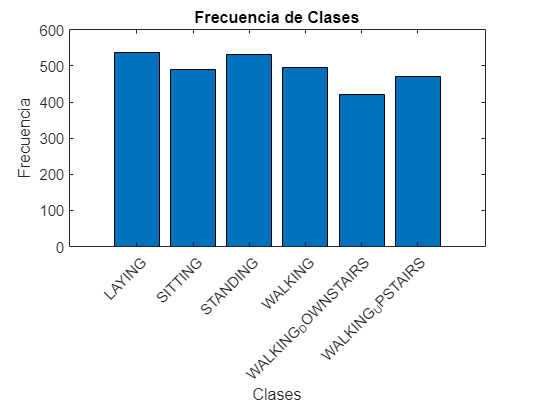

uniqueClasses = unique(dataCatY);
numClasses = numel(uniqueClasses);

classFrequencies = countcats(categorical(dataCatY)); % Frecuencias por cada clase

figure;
bar(classFrequencies);
xlabel('Clases');
ylabel('Frecuencia');
title('Frecuencia de Clases');
xticks(1:numClasses);
xticklabels(uniqueClasses);
xtickangle(45);

## Kernels lineales, polinomiales y gausianos

`Configuración de la validación cruzada`

num_folds = 5;
cv = cvpartition(length(dataY), 'KFold', num_folds);

precision_scores_lineal = zeros(1, num_folds);
precision_scores_gaus = zeros(1, num_folds);
precision_scores_poli = zeros(1, num_folds);

recall_scores_lineal = zeros(1, num_folds);
recall_scores_gaus = zeros(1, num_folds);
recall_scores_poli = zeros(1, num_folds);

f1_scores_lineal = zeros(1, num_folds);
f1_scores_gaus = zeros(1, num_folds);
f1_scores_poli = zeros(1, num_folds);

for fold = 1:num_folds
    % Indices para el conjunto de entrenamiento y prueba de este fold
    train_indices = cv.training(fold);
    test_indices = cv.test(fold);

    dataX_entrenamiento = dataX(train_indices, :);
    dataY_entrenamiento = dataY(train_indices);
    
    dataX_prueba = dataX(test_indices, :);
    dataY_prueba = dataY(test_indices);

    % Entrenar un SVM multiclase con kernel lineal, gausiano y polinomial
    SVMModel_lineal = fitcecoc(dataX_entrenamiento, dataY_entrenamiento, 'Learners', templateSVM('KernelFunction', 'linear'),'Coding', 'onevsone');
    predicciones_lineal = predict(SVMModel_lineal, dataX_prueba);
    SVMModel_gaus = fitcecoc(dataX_entrenamiento, dataY_entrenamiento, 'Learners', templateSVM('KernelFunction','gaussian','KernelScale', 2.4),'Coding', 'onevsone');
    predicciones_gaus = predict(SVMModel_gaus, dataX_prueba);
    SVMModel_poli = fitcecoc(dataX_entrenamiento, dataY_entrenamiento, 'Learners', templateSVM('KernelFunction', 'polynomial', 'PolynomialOrder', 2, 'KernelScale', 'auto'), 'Coding', 'onevsone');
    predicciones_poli = predict(SVMModel_poli, dataX_prueba);

    % Calcular las matrices de confusión
    matriz_confusion_lineal = confusionmat(dataY_prueba, predicciones_lineal);
    matriz_confusion_gaus = confusionmat(dataY_prueba, predicciones_gaus);
    matriz_confusion_poli = confusionmat(dataY_prueba, predicciones_poli);
    
    % Calcular precisión
    precision_lineal = sum(diag(matriz_confusion_lineal)) / sum(matriz_confusion_lineal(:));
    precision_scores_lineal(fold) = precision_lineal;
    precision_gaus = sum(diag(matriz_confusion_gaus)) / sum(matriz_confusion_gaus(:));
    precision_scores_gaus(fold) = precision_gaus;
    precision_poli = sum(diag(matriz_confusion_poli)) / sum(matriz_confusion_poli(:));
    precision_scores_poli(fold) = precision_poli;

    % Calcular recall
    recall_lineal = diag(matriz_confusion_lineal) ./ sum(matriz_confusion_lineal, 2);
    recall_scores_lineal(fold) = mean(recall_lineal);      
    recall_gaus = diag(matriz_confusion_gaus) ./ sum(matriz_confusion_gaus, 2);
    recall_scores_gaus(fold) = mean(recall_gaus);
    recall_poli = diag(matriz_confusion_poli) ./ sum(matriz_confusion_poli, 2);
    recall_scores_poli(fold) = mean(recall_poli);    

    % Calcular f1 score
    f1_lineal = 2 * (precision_lineal * recall_lineal) ./ (precision_lineal + recall_lineal);
    f1_scores_lineal(fold) = mean(f1_lineal);
    f1_gaus = 2 * (precision_gaus * recall_gaus) ./ (precision_gaus + recall_gaus);
    f1_scores_gaus(fold) = mean(f1_gaus);
    f1_poli = 2 * (precision_poli * recall_poli) ./ (precision_poli + recall_poli);
    f1_scores_poli(fold) = mean(f1_poli);
    
end

`Matriz de confusión`

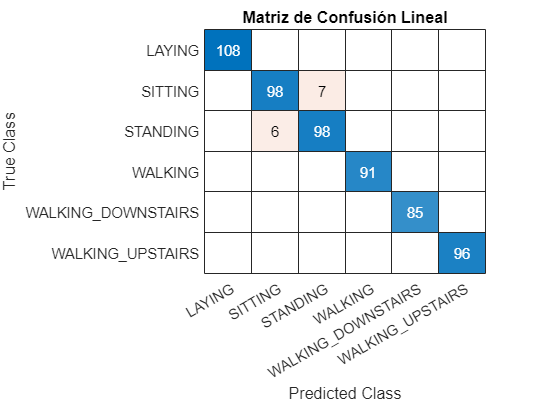

figure;
confusionchart(matriz_confusion_lineal, clases_unicas);
title('Matriz de Confusión Lineal');

`Matriz de confusión`

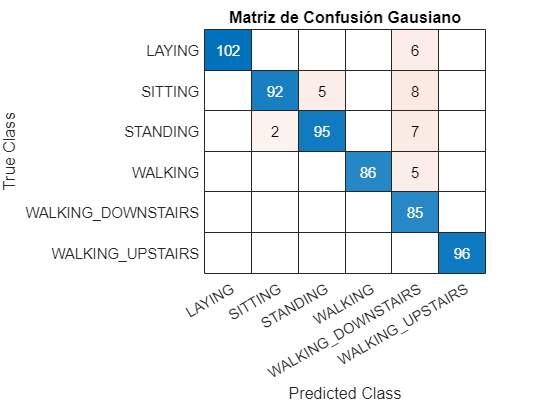

figure;
confusionchart(matriz_confusion_gaus, clases_unicas);
title('Matriz de Confusión Gausiano');

`Matriz de confusión`

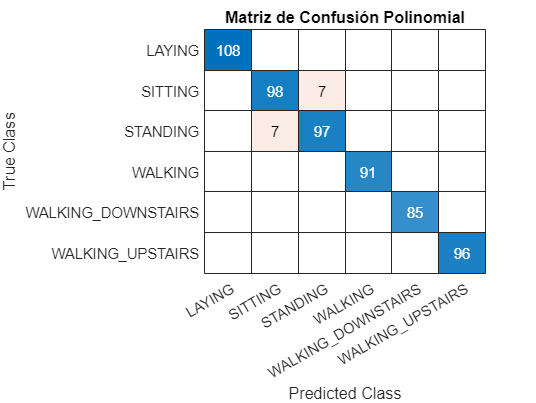

figure;
confusionchart(matriz_confusion_poli, clases_unicas);
title('Matriz de Confusión Polinomial');

Calculo de medias de las métricas para cada modelo

media_precision_lineal = mean(precision_scores_lineal);
disp("Precisión kernel lineal: " + media_precision_lineal);

Precisión kernel lineal: 0.98269


media_recall_lineal = mean(recall_scores_lineal);
disp("Recall kernel lineal: " + media_recall_lineal);

Recall kernel lineal: 0.98345


media_f1_lineal = mean(f1_scores_lineal);
disp("F1 Score kernel lineal: " + media_f1_lineal);

F1 Score kernel lineal: 0.98294



media_precision_gaus = mean(precision_scores_gaus);
disp("Precisión kernel gausiano: " + media_precision_gaus);

Precisión kernel gausiano: 0.93587


media_recall_gaus = mean(recall_scores_gaus);
disp("Recall kernel gausiano: " + media_recall_gaus);

Recall kernel gausiano: 0.938


media_f1_gaus = mean(f1_scores_gaus);
disp("F1 Score kernel gausiano: " + media_f1_gaus);

F1 Score kernel gausiano: 0.93636



media_precision_poli = mean(precision_scores_poli);
disp("Precisión kernel polinomial: " + media_precision_poli);

Precisión kernel polinomial: 0.98269


media_recall_poli = mean(recall_scores_poli);
disp("Recall kernel polinomial: " + media_recall_poli);

Recall kernel polinomial: 0.98344


media_f1_poli = mean(f1_scores_poli);
disp("F1 Score kernel polinomial: " + media_f1_poli);

F1 Score kernel polinomial: 0.98292


Visuaización consolidada por clases de métricas

modelos = ["Lineal"; "Gausiano"; "Polinomial"];

res_met_lineal = [media_precision_lineal, media_precision_gaus, media_precision_poli];
res_met_polin = [media_recall_lineal, media_recall_gaus, media_recall_poli];
res_met_gaus = [media_f1_lineal, media_f1_gaus, media_f1_poli];


resultados = table(modelos, res_met_lineal', res_met_polin', res_met_gaus');
resultados.Properties.VariableNames = {'Modelos', 'Precision', 'Recall', 'F1-score'};

disp(resultados);

      Modelos       Precision    Recall     F1-score
    ____________    _________    _______    ________

    "Lineal"         0.98269     0.98345    0.98294 
    "Gausiano"       0.93587       0.938    0.93636 
    "Polinomial"     0.98269     0.98344    0.98292 

